# **Desarrollo del Algoritmo**

clear all
close all

%%% Como el archivo es .csv, no te separa los datos, los pone por comas. Por eso leemos el archivo así:
raw = readcell('Data_SIN_ANOTACIONES.csv', 'FileType', 'spreadsheet');
textData = raw(:,1);
splitData = cellfun(@(x) strsplit(x, ','), textData, 'UniformOutput', false);
dataMatrix = vertcat(splitData{:});

headers = dataMatrix(1,:);
informacion = dataMatrix(2:end,:);

data = cell2table(informacion,'VariableNames',headers)

data = 726×19 table
           ImageName           GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Area    Leu_median_BoundingBox    Leu_median_Eccentricity    Leu_median_Circularity    Leu_median_Diameter      Leu_median_Solidity     Leu_median_Perimeter     Leu_median_Intensity     Par_median_Area    Par_median_BoundingBox    Par_median_Eccentricity    Par_median_Circularity    Par_median_Diameter      Par_median_Solidity     Par_median_Perimeter    Par_median_Intensity 
    _______________________    _________________________    ___________________    _______________    ______

## **1. Exploratory Data Analysis (EDA)**

#### Visión General

[alto, ancho] = size(data) % Osea, tenemos 292 imágenes y 19 variables

alto = 726

ancho = 19

variables = data.Properties.VariableNames

variables = 1×19 cell array
    {'ImageName'}    {'GlobulosBlancosDetectados'}    {'ParasitosDetectados'}    {'Leu_median_Area'}    {'Leu_median_BoundingBox'}    {'Leu_median_Eccentricity'}    {'Leu_median_Circularity'}    {'Leu_median_Diameter'}    {'Leu_median_Solidity'}    {'Leu_median_Perimeter'}    {'Leu_median_Intensity'}    {'Par_median_Area'}    {'Par_median_BoundingBox'}    {'Par_median_Eccentricity'}    {'Par_median_Circularity'}    {'Par_median_Diameter'}    {'Par_median_Solidity'}    {'Par_median_Perimeter'}    {'Par_median_Intensity'}


Las variables de las que disponemos son las siguientes:

- **ImageName**: nombre de la imagen 

- **GlobulosBlancosDetectados**: número de glóbulos blancos detectados en la imágen

- **ParasitosDetectados**: número de parásitos detectados en la imágen

- **Leu_median_Area**: mediana del área de los glóbulos blancos en la imágen (píxeles ^2)

- **Leu_median_BoundingBox**: mediana del BoundingBox de los glóbulos blancos en la imágen. Es decir, mediana entre las coordenadas x e y de los glóbulos blancos de la imágen y su alto y ancho.

- **Leu_median_Eccentricity**: mediana de la excentricidad de los glóbulos blancos en la imágen (sin unidad).

- **Leu_median_Circularity**: mediana de la circularidad de los glóbulos blancos en la imágen (sin unidad).

- **Leu_median_Diameter**: mediana del diámetro de los glóbulos blancos en la imágen (píxeles).

- **Leu_median_Solidity**: mediana  de la solidez los glóbulos blancos en la imágen (sin unidad).

- **Leu_median_Perimeter**: mediana del área de los glóbulos blancos en la imágen (píxeles).

- **Leu_median_Intensity**: mediana de la intensidad de los glóbulos blancos en la imágen (sin unidad).

- **Par_median_Area**: mediana del área de los parásitos en la imágen.

- **Par_median_BoundingBox**: mediana del BoundingBox de los parásitos en la imágen. Es decir, mediana entre las coordenadas x e y de los parásitos de la imágen y su alto y ancho.

- **Par_median_Eccentricity**: mediana de la excentricidad de los parásitos en la imágen.

- **Par_median_Circularity**: mediana de la circularidad de los parásitos en la imágen.

- **Par_median_Diamete**: mediana del diámetro de los parásitos en la imágen.

- **Par_median_Solidity**: mediana de la solidez de los parásitos en la imágen.

- **Par_median_Perimeter**: mediana del perímetro de los parásitos en la imágen.

- **Par_median_Intensity**: mediana de la intensidad de los parásitos en la imágen.

#### Adaptación de los Datos

1. Como el primer y último caracter de cada celda es una comilla, hay que eliminarlas para poder trabajar mejor con los datos, ya que si no, siempre se considerarán variables categóricas.

for i = 1:size(informacion, 1)
    for j = 1:size(informacion, 2)
        if ischar(informacion{i,j}) || isstring(informacion{i,j})
            % Eliminar comillas, espacios y caracteres no numéricos
            cleaned = strrep(informacion{i,j}, '''', '');
            cleaned = strrep(cleaned, '"', '');
            cleaned = strtrim(cleaned);  % Eliminar espacios al inicio/final
            
            % Reemplazar comas por puntos para decimales 
            cleaned = strrep(cleaned, ',', '.');
            
            % Intentar convertir a número
            num = str2double(cleaned);
            if ~isnan(num) || strcmpi(cleaned, 'nan') || strcmpi(cleaned, 'na')
                informacion{i,j} = num;
            else
                % Si no es convertible, mantener el texto original (pero limpio)
                informacion{i,j} = cleaned;
            end
        end
    end
end

data = cell2table(informacion,'VariableNames',headers)

data = 726×19 table
           ImageName           GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Area    Leu_median_BoundingBox    Leu_median_Eccentricity    Leu_median_Circularity    Leu_median_Diameter    Leu_median_Solidity    Leu_median_Perimeter    Leu_median_Intensity    Par_median_Area    Par_median_BoundingBox    Par_median_Eccentricity    Par_median_Circularity    Par_median_Diameter    Par_median_Solidity    Par_median_Perimeter    Par_median_Intensity
    _______________________    _________________________    ___________________    _______________    _______________

2. Como tenemos todos los datos en una misma tabla y nosotros queremos conocer las diferencias entre los 3 casos (infectados con *falciparum*, con *vivax* o sanos), hay que dividir la información.

Para eso, sabemos que los datos de *falciparum* van de la fila 1 a la 96 y que los sanos tienen 0 parásitos detectados.

idx_falciparum = 1:240;
idx_vivax = 241:486;
idx_sanos = 487:726;

#### Comprobar la desigualdad de clases

No existe una desigualdad entre las diferentes clases de infección.

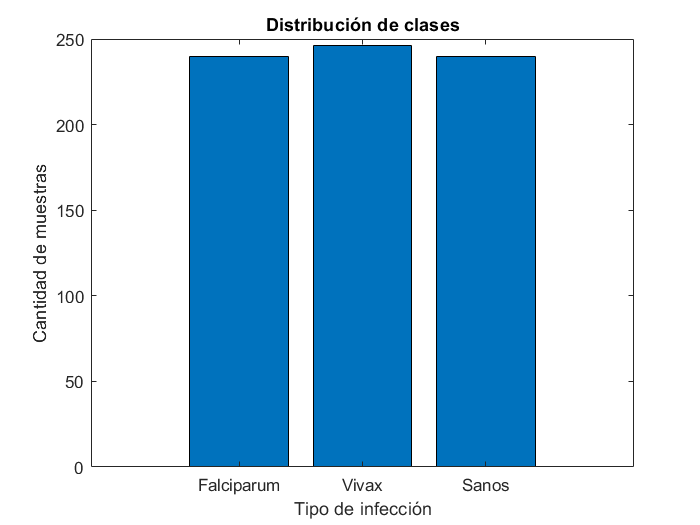

clases = {'Falciparum', 'Vivax', 'Sanos'};
cantidades = [length(idx_falciparum), length(idx_vivax), length(idx_sanos)];

figure;
bar(cantidades)
set(gca, 'XTickLabel', clases);
xlabel('Tipo de infección');
ylabel('Cantidad de muestras');
title('Distribución de clases');

#### **Estadísticas Descriptivas **

Primero de todo, vamos a analizar si la variable es numérica o categórica. En el caso de ser categórica, se indicará mediante un mensaje. En cambio, en el caso de ser numérica, se calculará la medoa, la moda, el máximo, el mínimo, la derivación estándar, la varianza y el número de datos faltantes por variable.

for i=1:ancho
    x=data.(variables{i});
    if isnumeric(x)
        fprintf ('Variable: %s\n', variables {i});
        fprintf ('Mean %.2f\n', mean (x, 'omitnan'));
        fprintf ('Mode %.2f\n', mode (x));
        fprintf ('Max %.2f\n', max (x));
        fprintf ('Min %.2f\n', min (x));
        fprintf ('Derivación estándar %.2f\n', std (x, 'omitnan'));
        fprintf ('Varianza %.2f\n', (std (x, 'omitnan'))^2);
        missingCount = sum(ismissing(x));
        fprintf('Datos faltantes: %d\n\n', missingCount);
    else
        fprintf ('Variable: %s es categórica.\n', variables{i});
    end
end 

Variable: ImageName es categórica.


Variable: GlobulosBlancosDetectados


Mean 20.88


Mode 19.00


Max 61.00


Min 3.00


Derivación estándar 9.18


Varianza 84.36


Datos faltantes: 0



Variable: ParasitosDetectados


Mean 32.73


Mode 2.00


Max 214.00


Min 0.00


Derivación estándar 35.33


Varianza 1247.86


Datos faltantes: 0



Variable: Leu_median_Area


Mean 3110.84


Mode 3380.00


Max 5970.00


Min 342.50


Derivación estándar 1148.45


Varianza 1318946.59


Datos faltantes: 0



Variable: Leu_median_BoundingBox


Mean 280.15


Mode 182.75


Max 677.25


Min 98.75


Derivación estándar 101.03


Varianza 10206.52


Datos faltantes: 0



Variable: Leu_median_Eccentricity


Mean 0.66


Mode 0.38


Max 0.87


Min 0.38


Derivación estándar 0.10


Varianza 0.01


Datos faltantes: 0



Variable: Leu_median_Circularity


Mean 0.67


Mode 0.31


Max 0.99


Min 0.31


Derivación estándar 0.13


Varianza 0.02


Datos faltantes: 0



Variable: Leu_median_Diameter


Mean 61.45


Mode 56.88


Max 87.19


Min 20.88


Derivación estándar 13.45


Varianza 180.86


Datos faltantes: 0



Variable: Leu_median_Solidity


Mean 0.88


Mode 0.69


Max 0.98


Min 0.69


Derivación estándar 0.05


Varianza 0.00


Datos faltantes: 0



Variable: Leu_median_Perimeter


Mean 235.82


Mode 205.14


Max 364.67


Min 89.07


Derivación estándar 47.57


Varianza 2263.20


Datos faltantes: 0



Variable: Leu_median_Intensity


Mean 0.16


Mode 0.09


Max 0.25


Min 0.09


Derivación estándar 0.04


Varianza 0.00


Datos faltantes: 0



Variable: Par_median_Area


Mean 196.54


Mode 130.00


Max 581.00


Min 83.00


Derivación estándar 68.54


Varianza 4697.80


Datos faltantes: 23



Variable: Par_median_BoundingBox


Mean 313.92


Mode 150.25


Max 1220.75


Min 63.75


Derivación estándar 179.34


Varianza 32164.55


Datos faltantes: 23



Variable: Par_median_Eccentricity


Mean 0.63


Mode 0.32


Max 0.89


Min 0.32


Derivación estándar 0.07


Varianza 0.01


Datos faltantes: 23



Variable: Par_median_Circularity


Mean 0.90


Mode 0.87


Max 1.15


Min 0.69


Derivación estándar 0.06


Varianza 0.00


Datos faltantes: 23



Variable: Par_median_Diameter


Mean 15.57


Mode 14.67


Max 27.20


Min 10.28


Derivación estándar 2.58


Varianza 6.65


Datos faltantes: 23



Variable: Par_median_Solidity


Mean 0.92


Mode 0.91


Max 0.98


Min 0.85


Derivación estándar 0.02


Varianza 0.00


Datos faltantes: 23



Variable: Par_median_Perimeter


Mean 52.17


Mode 42.53


Max 95.57


Min 31.37


Derivación estándar 9.26


Varianza 85.73


Datos faltantes: 23



Variable: Par_median_Intensity


Mean 0.54


Mode 0.24


Max 0.67


Min 0.24


Derivación estándar 0.08


Varianza 0.01


Datos faltantes: 23



#### Datos que faltan

Hay que identificar los datos que faltan para decidir qué hacer con ellos y cómo continuar con el EDA.

La única data faltante que tenemos es la relacionada con parásitos, ya que los pacientes sanos no tienen parásitos. A pesar de que el porcentaje de datos faltantes en estas variables es mayor que el 30%, no podemos eliminar dichas variables, ya que contienen también información a cerca de los pacientes contagiados. Es por eso, por lo que se ha optado por ignorar esos datos faltantes, imputando los valores perdidos. **En el caso de obtener resultados poco fiables, se analizarán más muestras contagiadas.**

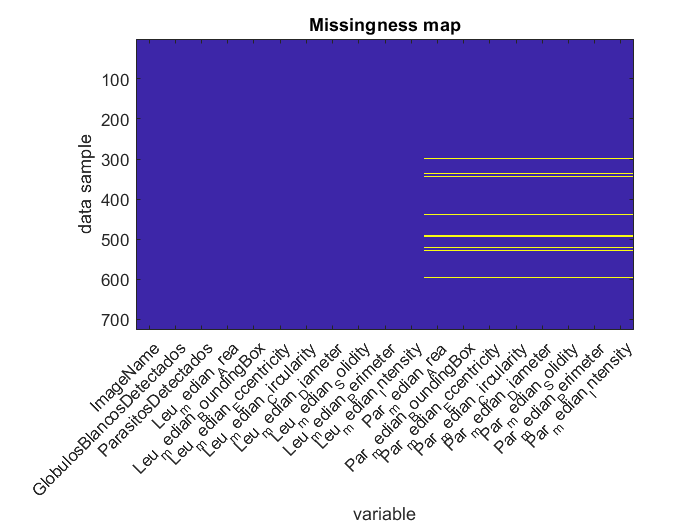

figure;
names = data.Properties.VariableNames;
imagesc(ismissing(data,{'' '.' 'NA' NaN -99}))
xticks(1:length(names));
xticklabels(names);
xtickangle(45)
title('Missingness map');
xlabel('variable');
ylabel('data sample');

summary(data)

Variables:

    ImageName: 726×1 cell array of character vectors

    GlobulosBlancosDetectados: 726×1 double

        Values:

            Min           3   
            Median       19   
            Max          61   

    ParasitosDetectados: 726×1 double

        Values:

            Min           0   
            Median       20   
            Max         214   

    Leu_median_Area: 726×1 double

        Values:

            Min         342.5 
            Median     3335.5 
            Max          5970 

    Leu_median_BoundingBox: 726×1 double

        Values:

            Min         98.75 
            Median     263.25 
            Max        677.25 

    Leu_median_Eccentricity: 726×1 double

        Values:

            Min       0.37724 
            Median    0.67068 
            Max       0.87488 

    Leu_median_Circularity: 726×1 double

        Values


[alto, ancho] = size(data);

Leu_Area_Missing = 99/alto*100

Leu_Area_Missing = 13.6364

Leu_BB_Missing = 99/alto*100

Leu_BB_Missing = 13.6364

Leu_Excentricidad_Missing = 99/alto*100

Leu_Excentricidad_Missing = 13.6364

Leu_Circularidad_Missing = 99/alto*100

Leu_Circularidad_Missing = 13.6364

Leu_Diametro_Missing = 99/alto*100

Leu_Diametro_Missing = 13.6364

Leu_Solidez_Missing = 99/alto*100

Leu_Solidez_Missing = 13.6364

Leu_Perimetro_Missing = 99/alto*100

Leu_Perimetro_Missing = 13.6364

Leu_Intensidad_Missing = 99/alto*100

Leu_Intensidad_Missing = 13.6364


Par_Area_Missing = 98/alto*100

Par_Area_Missing = 13.4986

Par_BB_Missing = 98/alto*100

Par_BB_Missing = 13.4986

Par_Excentricidad_Missing = 98/alto*100

Par_Excentricidad_Missing = 13.4986

Par_Circularidad_Missing = 98/alto*100

Par_Circularidad_Missing = 13.4986

Par_Diametro_Missing = 98/alto*100

Par_Diametro_Missing = 13.4986

Par_Solidez_Missing = 98/alto*100

Par_Solidez_Missing = 13.4986

Par_Perimetro_Missing = 98/alto*100

Par_Perimetro_Missing = 13.4986

Par_Intensidad_Missing = 98/alto*100

Par_Intensidad_Missing = 13.4986


% A = mean(data.Par_median_Area, 'omitnan');
% A = data.Par_median_Area(isnan(data.Par_median_Area));
% 
% B = mean(data.Par_median_BoundingBox, 'omitnan');
% B = data.Par_median_BoundingBox(isnan(data.Par_median_BoundingBox));
% 
% C = mean(data.Par_median_Eccentricity, 'omitnan');
% C = data.Par_median_Eccentricity(isnan(data.Par_median_Eccentricity));
% 
% D = mean(data.Par_median_Circularity, 'omitnan');
% D = data.Par_median_Circularity(isnan(data.Par_median_Circularity));
% 
% E = mean(data.Par_median_Diameter, 'omitnan');
% E = data.Par_median_Diameter(isnan(data.Par_median_Diameter));
% 
% F = mean(data.Par_median_Solidity, 'omitnan');
% F = data.Par_median_Solidity(isnan(data.Par_median_Solidity));
% 
% G = mean(data.Par_median_Perimeter, 'omitnan');
% G = data.Par_median_Perimeter(isnan(data.Par_median_Perimeter));
% 
% H = mean(data.Par_median_Intensity, 'omitnan');
% H = data.Par_median_Intensity(isnan(data.Par_median_Intensity));

data

data = 726×19 table
           ImageName           GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Area    Leu_median_BoundingBox    Leu_median_Eccentricity    Leu_median_Circularity    Leu_median_Diameter    Leu_median_Solidity    Leu_median_Perimeter    Leu_median_Intensity    Par_median_Area    Par_median_BoundingBox    Par_median_Eccentricity    Par_median_Circularity    Par_median_Diameter    Par_median_Solidity    Par_median_Perimeter    Par_median_Intensity
    _______________________    _________________________    ___________________    _______________    _______________

#### Datos duplicados

Además de analizar los datos faltantes, también hay que saber qué datos se repiten para poder continuar con el análisis de forma correcta. Observamos que no hay datos repetidos.

height(unique(data,'rows'))

ans = 726

#### Figuras

1. A continuación se graficarán diversos histogramas para analizar las diferencias en la cantidad de glóbulos blancos detectados en las muestras afectadas por la malaria y las no afectadas.

A partir de la bibliografía analizada, se sabe que la cantidad de glóbulos blancos en pacientes sanos es mayor que en pacientes infectados. A su vez, se conoce que la cantidad en pacientes con malaria de tipo *falciparum* es mayor que en los pacientes con el tipo *vivax*.

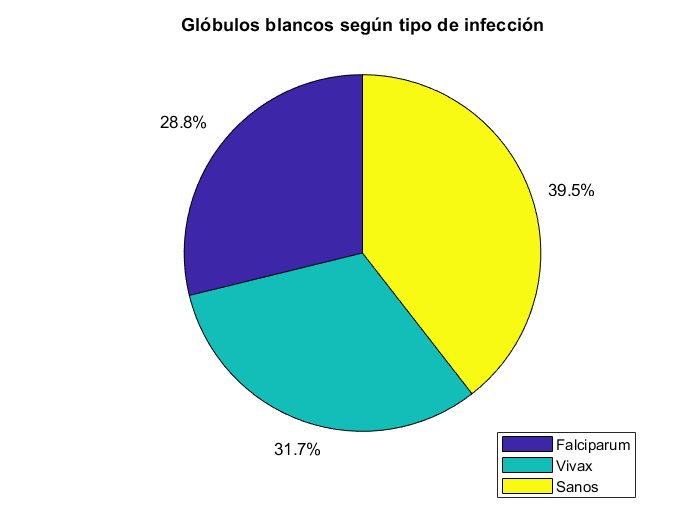

falciparum_globulos = data.GlobulosBlancosDetectados(idx_falciparum);
vivax_globulos = data.GlobulosBlancosDetectados(idx_vivax);
sanos_globulos = data.GlobulosBlancosDetectados(idx_sanos);

falciparum_globulos_cantidad = mean(falciparum_globulos, 'omitnan');
vivax_globulos_cantidad = mean(vivax_globulos, 'omitnan');
sanos_globulos_cantidad = mean(sanos_globulos, 'omitnan');

figure;
valores = [falciparum_globulos_cantidad, vivax_globulos_cantidad, sanos_globulos_cantidad];
porcentajes = 100 * valores / sum(valores);
etiquetas = strcat(string(round(porcentajes,1)), '%'); 
pie(valores, etiquetas);
title('Glóbulos blancos según tipo de infección');
legend({'Falciparum', 'Vivax', 'Sanos'},"Position",[0.66051,0.0079702,0.2971,0.21236])

2. Se realizará el mismo procedimiento con los parásitos detectados.

A partir de la bibliografía analizada, se sabe que la cantidad de parásitos en pacientes sanos es nula y que la cantidad de parásitos en pacientes con *falciparum* es mayor que en los pacientes con *vivax*.

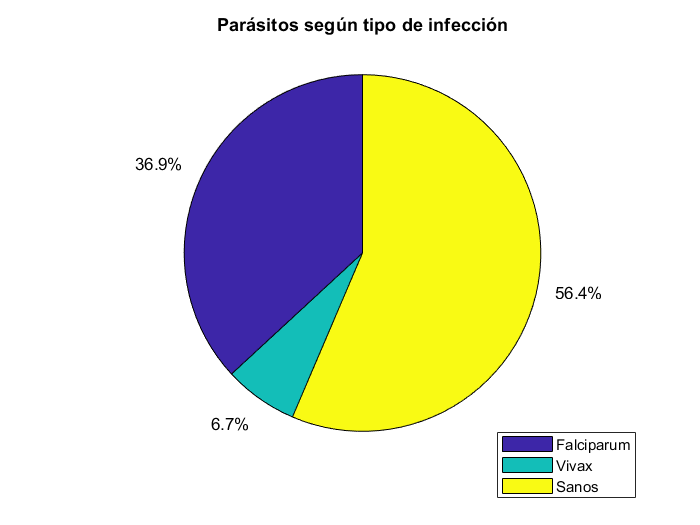

falciparum_parasitos = data.ParasitosDetectados(idx_falciparum);
vivax_parasitos = data.ParasitosDetectados(idx_vivax);
sanos_parasitos = data.ParasitosDetectados(idx_sanos);

falciparum_parasitos_cantidad = median(falciparum_parasitos, 'omitnan');
vivax_parasitos_cantidad = median(vivax_parasitos, 'omitnan');
sanos_parasitos_cantidad = median(sanos_parasitos, 'omitnan');

figure;
valores = [falciparum_parasitos_cantidad, vivax_parasitos_cantidad, sanos_parasitos_cantidad];
porcentajes = 100 * valores / sum(valores);
etiquetas = strcat(string(round(porcentajes,1)), '%'); 
pie(valores, etiquetas);
title('Parásitos según tipo de infección');
legend({'Falciparum', 'Vivax', 'Sanos'},"Position",[0.66051,0.0079702,0.2971,0.21236])

3. Ahora analizaremos de qué manera las características obtenidas  cambian en función del tipo de infección para ver si existe algún patrón.

ÁREA:

Observamos que el tamaño de los parásitos de tipo *vivax* es considerablemente mayor al tamaño de los parásitos *falciparum*, tal y como dice la bibliografía analizada.

Sin embargo, también se ha analizado la considerable diferencia obtenida en el tamaño de los glóbulos blancos en pacientes con diferentes tipos de infección. **Se desconoce el motivo.**

% falciparum_globulos_area = data.Leu_median_Area(idx_falciparum);
% vivax_globulos_area = data.Leu_median_Area(idx_vivax);
% sanos_globulos_area = data.Leu_median_Area(idx_sanos);
% 
% valores_area = [falciparum_globulos_area; vivax_globulos_area; sanos_globulos_area];
% 
% grupo = [repmat({'Falciparum'}, length(falciparum_globulos_area), 1); 
%          repmat({'Vivax'}, length(vivax_globulos_area), 1); 
%          repmat({'Sanos'}, length(sanos_globulos_area), 1)];
% 
% figure;
% subplot(1,2,1);
% boxplot(valores_area, grupo);
% xlabel('Tipo de infección');
% ylabel('Área glóbulos blancos');
% title('Área leuc.');
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% falciparum_parasitos_area = data.Par_median_Area(idx_falciparum);
% vivax_parasitos_area = data.Par_median_Area(idx_vivax);
% sanos_parasitos_area = data.Par_median_Area(idx_sanos);
% 
% valores_area = [falciparum_parasitos_area; vivax_parasitos_area; sanos_parasitos_area];
% 
% grupo = [repmat({'Falciparum'}, length(falciparum_parasitos_area), 1); 
%          repmat({'Vivax'}, length(vivax_parasitos_area), 1); 
%          repmat({'Sanos'}, length(sanos_parasitos_area), 1)];
% 
% subplot(1,2,2);
% boxplot(valores_area, grupo);
% xlabel('Tipo de infección');
% ylabel('Área parásitos');
% title('Área par.');

EXCENTRICIDAD:

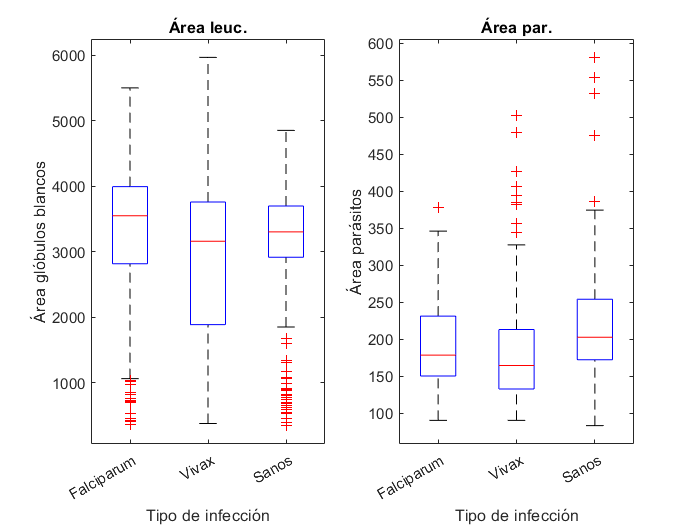

% falciparum_globulos_excentricidad = data.Leu_median_Eccentricity(idx_falciparum);
% vivax_globulos_excentricidad = data.Leu_median_Eccentricity(idx_vivax);
% sanos_globulos_excentricidad = data.Leu_median_Eccentricity(idx_sanos);
% 

% valores_area = [falciparum_globulos_excentricidad; vivax_globulos_excentricidad; sanos_globulos_excentricidad];
% 
% grupo = [repmat({'Falciparum'}, length(falciparum_globulos_excentricidad), 1); 
%          repmat({'Vivax'}, length(vivax_globulos_excentricidad), 1); 
%          repmat({'Sanos'}, length(sanos_globulos_excentricidad), 1)];
% 
% figure;
% subplot(1,2,1);
% boxplot(valores_area, grupo);
% xlabel('Tipo de infección');
% ylabel('Excentricidad glóbulos blancos');
% title('Excentricidad leuc.');
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% falciparum_parasitos_excentricidad = data.Par_median_Eccentricity(idx_falciparum);
% vivax_parasitos_excentricidad = data.Par_median_Eccentricity(idx_vivax);
% sanos_parasitos_excentricidad = data.Par_median_Eccentricity(idx_sanos);
% 
% valores_area = [falciparum_parasitos_excentricidad; vivax_parasitos_excentricidad; sanos_parasitos_excentricidad];
% 
% grupo = [repmat({'Falciparum'}, length(falciparum_parasitos_excentricidad), 1); 
%          repmat({'Vivax'}, length(vivax_parasitos_excentricidad), 1); 
%          repmat({'Sanos'}, length(sanos_parasitos_excentricidad), 1)];
% 
% subplot(1,2,2);
% boxplot(valores_area, grupo);
% xlabel('Tipo de infección');
% ylabel('Excentricidad parásitos');
% title('Excentricidad par.');

CIRCULARIDAD:

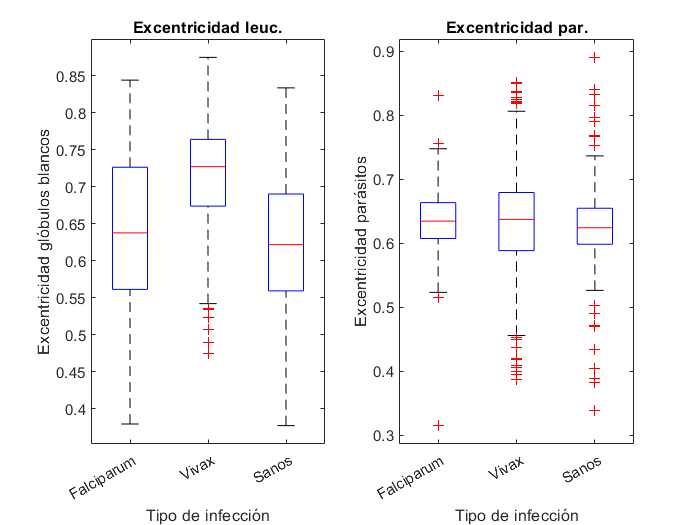

% falciparum_globulos_circularidad = data.Leu_median_Circularity(idx_falciparum);
% vivax_globulos_circularidad = data.Leu_median_Circularity(idx_vivax);
% sanos_globulos_circularidad = data.Leu_median_Circularity(idx_sanos);
% 
% valores_area = [falciparum_globulos_circularidad; vivax_globulos_circularidad; sanos_globulos_circularidad];

% 
% grupo = [repmat({'Falciparum'}, length(falciparum_globulos_circularidad), 1); 
%          repmat({'Vivax'}, length(vivax_globulos_circularidad), 1); 
%          repmat({'Sanos'}, length(sanos_globulos_circularidad), 1)];
% 
% figure;
% subplot(1,2,1);
% boxplot(valores_area, grupo);
% xlabel('Tipo de infección');
% ylabel('Circularidad glóbulos blancos');
% title('Circularidad leuc.');
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% falciparum_parasitos_excentricidad = data.Par_median_Eccentricity(idx_falciparum);
% vivax_parasitos_excentricidad = data.Par_median_Eccentricity(idx_vivax);
% sanos_parasitos_excentricidad = data.Par_median_Eccentricity(idx_sanos);
% 
% valores_area = [falciparum_parasitos_excentricidad; vivax_parasitos_excentricidad; sanos_parasitos_excentricidad];
% 
% grupo = [repmat({'Falciparum'}, length(falciparum_parasitos_excentricidad), 1); 
%          repmat({'Vivax'}, length(vivax_parasitos_excentricidad), 1); 
%          repmat({'Sanos'}, length(sanos_parasitos_excentricidad), 1)];
% 
% subplot(1,2,2);
% boxplot(valores_area, grupo);
% xlabel('Tipo de infección');
% ylabel('Circularidad parásitos');
% title('Circularidad par.');

SOLIDEZ:

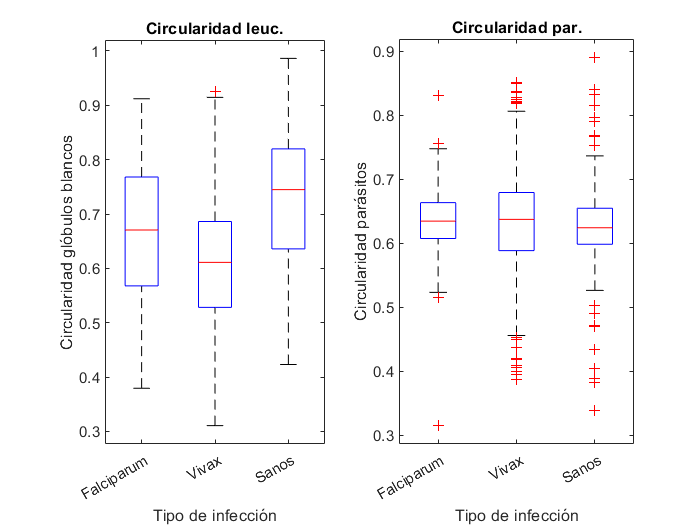

% falciparum_globulos_solidez = data.Leu_median_Solidity(idx_falciparum);
% vivax_globulos_solidez = data.Leu_median_Solidity(idx_vivax);
% sanos_globulos_solidez = data.Leu_median_Solidity(idx_sanos);
% 
% valores_area = [falciparum_globulos_solidez; vivax_globulos_solidez; sanos_globulos_solidez];
% 

% grupo = [repmat({'Falciparum'}, length(falciparum_globulos_solidez), 1); 
%          repmat({'Vivax'}, length(vivax_globulos_solidez), 1); 
%          repmat({'Sanos'}, length(sanos_globulos_solidez), 1)];
% 
% figure;
% subplot(1,2,1);
% boxplot(valores_area, grupo);
% xlabel('Tipo de infección');
% ylabel('Solidez glóbulos blancos');
% title('Soldiez leuc.');
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% falciparum_parasitos_solidez = data.Par_median_Solidity(idx_falciparum);
% vivax_parasitos_solidez = data.Par_median_Solidity(idx_vivax);
% sanos_parasitos_solidez = data.Par_median_Solidity(idx_sanos);
% 
% valores_area = [falciparum_parasitos_solidez; vivax_parasitos_solidez; sanos_parasitos_solidez];
% 
% grupo = [repmat({'Falciparum'}, length(falciparum_parasitos_solidez), 1); 
%          repmat({'Vivax'}, length(vivax_parasitos_solidez), 1); 
%          repmat({'Sanos'}, length(sanos_parasitos_solidez), 1)];
% 
% subplot(1,2,2);
% boxplot(valores_area, grupo);
% xlabel('Tipo de infección');
% ylabel('Solidez parásitos');
% title('Solidez par.');

INTENSIDAD:

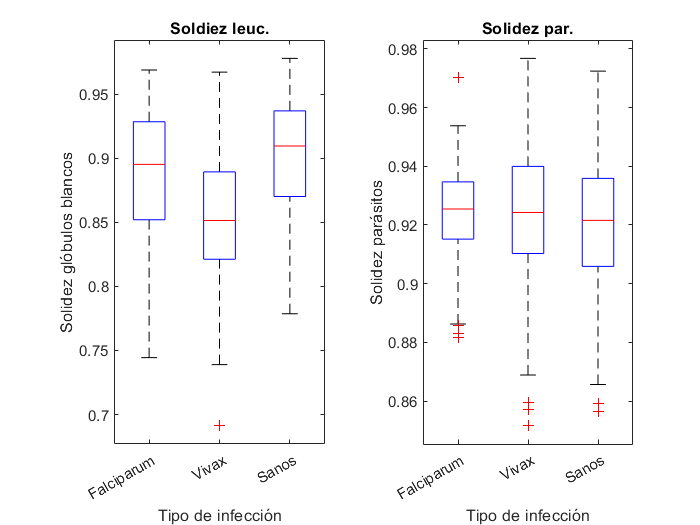

% falciparum_globulos_intensidad = data.Leu_median_Intensity(idx_falciparum);
% vivax_globulos_intensidad = data.Leu_median_Intensity(idx_vivax);
% sanos_globulos_intensidad = data.Leu_median_Intensity(idx_sanos);
% 
% valores_area = [falciparum_globulos_intensidad; vivax_globulos_intensidad; sanos_globulos_intensidad];
% 
% grupo = [repmat({'Falciparum'}, length(falciparum_globulos_intensidad), 1); 

%          repmat({'Vivax'}, length(vivax_globulos_intensidad), 1); 
%          repmat({'Sanos'}, length(sanos_globulos_intensidad), 1)];
% 
% figure;
% subplot(1,2,1);
% boxplot(valores_area, grupo);
% xlabel('Tipo de infección');
% ylabel('Intensidad glóbulos blancos');
% title('Intensidad leuc.');
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% falciparum_parasitos_intensidad = data.Par_median_Intensity(idx_falciparum);
% vivax_parasitos_intensidad = data.Par_median_Intensity(idx_vivax);
% sanos_parasitos_intensidad = data.Par_median_Intensity(idx_sanos);
% 
% valores_area = [falciparum_parasitos_intensidad; vivax_parasitos_intensidad; sanos_parasitos_intensidad];
% 
% grupo = [repmat({'Falciparum'}, length(falciparum_parasitos_intensidad), 1); 
%          repmat({'Vivax'}, length(vivax_parasitos_intensidad), 1); 
%          repmat({'Sanos'}, length(sanos_parasitos_intensidad), 1)];
% 
% subplot(1,2,2);
% boxplot(valores_area, grupo);
% xlabel('Tipo de infección');
% ylabel('Intensidad parásitos');
% title('Intensidad par.');
% data;

#### Comprobar valores atípicos

Una vez se pueden ver los valores de forma visual gracias a los Box Plots, se va a proceder a desarrollar el IQR (Interquartile Range) para ver los valores atípicos de forma matemática.

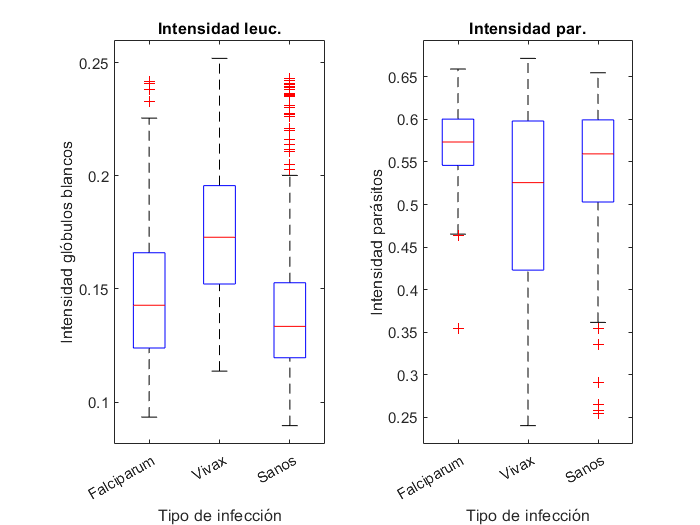

Group_Names = {'falciparum', 'vivax', 'sanos'};
Group_Indices = {idx_falciparum, idx_vivax, idx_sanos};
Outliers_All = [];

for g = 1:3

    idx = Group_Indices{g};
    data_group = data(idx, :);

    Outliers_count = [];
    Variable_names = {};

    for i = 1:width(data_group)
        var_name = data_group.Properties.VariableNames{i};
        x = data_group.(var_name);

        if isnumeric(x)
            Q1 = quantile(x(~isnan(x)), 0.25);
            Q3 = quantile(x(~isnan(x)), 0.75);
            IQR_val = Q3 - Q1;
    
            lower_limit = Q1 - 1.5 * IQR_val;
            upper_limit = Q3 + 1.5 * IQR_val;
    
            is_outlier = x < lower_limit | x > upper_limit;
            count_outliers = sum(is_outlier, 'omitnan');
    
            Variable_names{end+1} = var_name;
            Outliers_count(end+1) = count_outliers;

            if g == 1
                data.([var_name '_outlier']) = false(height(data), 1); % Crear columna
            end
            data.([var_name '_outlier'])(idx) = is_outlier;
        end
    end
    Outliers_Summary = table(Variable_names', Outliers_count','VariableNames', {'Variable', 'OutliersCount'});
    Outliers_Summary.Group = repmat(Group_Names(g), height(Outliers_Summary), 1);
    Outliers_All = [Outliers_All; Outliers_Summary];
end
display(Outliers_All);
data

#### Corrección de alguna variable

A pesar de contar con la variable BoundingBox, esta no otorga ninguna información útil para poder desarrollar un análisis. Y es que, esta variable es el resultado de calcular la media de las coordenadas (x e y) y el alto y ancho de los glóbulos blancos y parásitos. De modo que se ha decidido eliminar esta variable.

data.Leu_median_BoundingBox = [];

Outliers_All = 54×3 table
              Variable               OutliersCount        Group     
    _____________________________    _____________    ______________

    {'GlobulosBlancosDetectados'}         11          {'falciparum'}
    {'ParasitosDetectados'      }          1          {'falciparum'}
    {'Leu_median_Area'          }         17          {'falciparum'}
    {'Leu_median_BoundingBox'   }          1          {'falciparum'}
    {'Leu_median_Eccentricity'  }          0          {'falciparum'}
    {'Leu_median_Circularity'   }          0          {'falciparum'}
    {'Leu_median_Diameter'      }         24          {'falciparum'}
    {'Leu_median_Solidity'      }          0          {'falciparum'}
    {'Leu_median_Perimeter'     }         14          {'falciparum'}
    {'Leu_median_Intensity'     }          4          {'falciparum'}
    {'Par_median_Area'          }          

data.Par_median_BoundingBox = [];

data = 726×37 table
           ImageName           GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Area    Leu_median_BoundingBox    Leu_median_Eccentricity    Leu_median_Circularity    Leu_median_Diameter    Leu_median_Solidity    Leu_median_Perimeter    Leu_median_Intensity    Par_median_Area    Par_median_BoundingBox    Par_median_Eccentricity    Par_median_Circularity    Par_median_Diameter    Par_median_Solidity    Par_median_Perimeter    Par_median_Intensity    GlobulosBlancosDetectados_outlier    ParasitosDetectados_outlier    Leu_median_Area_outlier    Leu_median_BoundingBox_outlier

Data_Sin_BoundingBox = data % sin boundingbox

#### Correlación

Hay que analizar la correlación entre las variables para ver si las diferentes variables tienen alguna relación entre ellas.

is_numeric = varfun(@isnumeric, data, 'OutputFormat', 'uniform');
numeric_data = data(:, is_numeric);
high_correlations = corr(table2array(numeric_data), 'Rows', 'pairwise');

Data_Sin_BoundingBox = 726×35 table
           ImageName           GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Area    Leu_median_Eccentricity    Leu_median_Circularity    Leu_median_Diameter    Leu_median_Solidity    Leu_median_Perimeter    Leu_median_Intensity    Par_median_Area    Par_median_Eccentricity    Par_median_Circularity    Par_median_Diameter    Par_median_Solidity    Par_median_Perimeter    Par_median_Intensity    GlobulosBlancosDetectados_outlier    ParasitosDetectados_outlier    Leu_median_Area_outlier    Leu_median_BoundingBox_outlier    Leu_median_Eccentricity_outlier    Leu

[row, col] = find(abs(high_correlations) > 0.95 & abs(high_correlations) < 1);
pairs_reported = zeros(0,2);

for k = 1:length(row)
    i = row(k);
    j = col(k);

    if i < j && ~any(ismember([i,j], pairs_reported, 'rows')) 
        var1 = numeric_data.Properties.VariableNames{i};
        var2 = numeric_data.Properties.VariableNames{j};
        fprintf('Variables altamente correlacionadas: %s and %s (r = %.2f)\n', var1, var2, high_correlations(i,j));
    end
end

figure;
heatmap(high_correlations, 'Colormap', parula, 'ColorLimits', [-1 1]);
title('Matriz de correlación');

Variables altamente correlacionadas: Leu_median_Area and Leu_median_Diameter (r = 0.99)
Variables altamente correlacionadas: Par_median_Area and Par_median_Diameter (r = 0.99)
Variables altamente correlacionadas: Par_median_Area and Par_median_Perimeter (r = 0.96)
Variables altamente correlacionadas: Par_median_Diameter and Par_median_Perimeter (r = 0.97)


Podemos ver que existen algunas correlaciones, de modo que en el preprocesamiento vamos a eliminar algunas variables.

## PREPROCESAMIENTO

Una vez entendidos nuestros datos, se va a proceder a llevar a cabo el preprocesamiento.

#### Eliminar datos redundantes

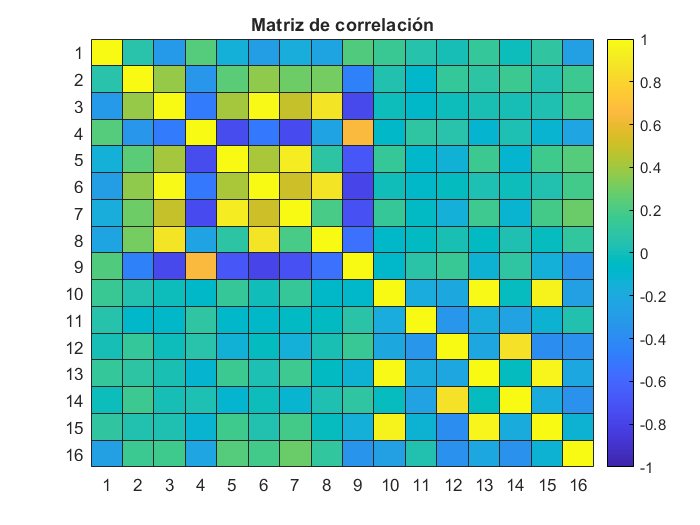

data.ImageName = [];
%data.GlobulosBlancosDetectados = [];
%data.ParasitosDetectados = [];

data.Leu_median_Diameter = [];
data.Par_median_Diameter = [];
data.Leu_median_Eccentricity = [];
data.Par_median_Eccentricity = [];
data.Leu_median_Solidity = [];
data.Par_median_Solidity = [];
data.Leu_median_Area = [];
data.Par_median_Area = [];
data.Leu_median_Perimeter = [];
data.Par_median_Perimeter = [];
Data_Sin_Redundantes = data;

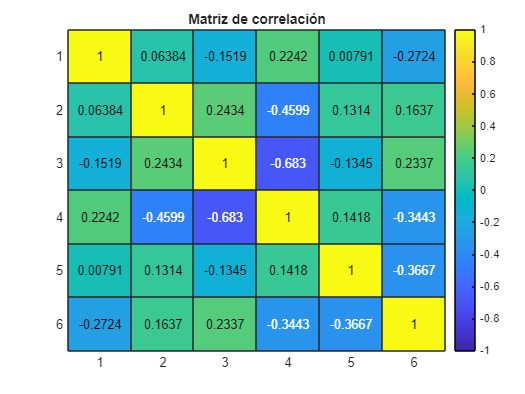

is_numeric = varfun(@isnumeric, data, 'OutputFormat', 'uniform');
numeric_data = data(:, is_numeric);
high_correlations = corr(table2array(numeric_data), 'Rows', 'pairwise');
[row, col] = find(abs(high_correlations) > 0.95 & abs(high_correlations) < 1);
pairs_reported = zeros(0,2);

for k = 1:length(row)
    i = row(k);
    j = col(k);

    if i < j && ~any(ismember([i,j], pairs_reported, 'rows')) 
        var1 = numeric_data.Properties.VariableNames{i};
        var2 = numeric_data.Properties.VariableNames{j};
        fprintf('Variables altamente correlacionadas: %s and %s (r = %.2f)\n', var1, var2, high_correlations(i,j));
    end
end

figure;
heatmap(high_correlations, 'Colormap', parula, 'ColorLimits', [-1 1]);
title('Matriz de correlación');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pearson
% corr_falciparum = corr(data.Leu_median_Area(idx_falciparum), data.Par_median_Area(idx_falciparum), 'Rows', 'complete');
% disp(['Correlación área: ', num2str(corr_falciparum)]);
% corr_falciparum = corr(data.Leu_median_Perimeter(idx_falciparum), data.Par_median_Perimeter(idx_falciparum), 'Rows', 'complete');
% disp(['Correlación perímetro: ', num2str(corr_falciparum)]);
% 
% [corr_coef, p_val] = corr(data.Leu_median_Area, data.Par_median_Area, 'Rows', 'complete');

% disp(['p-valor: ', num2str(p_val)]);
% [corr_coef, p_val] = corr(data.Leu_median_Perimeter, data.Par_median_Perimeter, 'Rows', 'complete');
% disp(['p-valor: ', num2str(p_val)]);

#### **Establecer clases**

Antes de continuar con el análisis, vamos a crear una columna que claramente diga qué tipo de infección tiene la muestra.

labels = cell(height(data), 1); 
labels(1:240) = {'falciparum'};
labels(241:486) = {'vivax'};
labels(487:726) = {'sano'};
data = addvars(data, labels, 'Before', 1, 'NewVariableNames', 'Clase');
data

data = 726×25 table
        Clase         GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Circularity    Leu_median_Intensity    Par_median_Circularity    Par_median_Intensity    GlobulosBlancosDetectados_outlier    ParasitosDetectados_outlier    Leu_median_Area_outlier    Leu_median_BoundingBox_outlier    Leu_median_Eccentricity_outlier    Leu_median_Circularity_outlier    Leu_median_Diameter_outlier    Leu_median_Solidity_outlier    Leu_median_Perimeter_outlier    Leu_median_Intensity_outlier    Par_median_Area_outlier    Par_median_BoundingBox_outlier    Par_median_Eccentricity_outlier    Par_median_Circularity_outlier

#### Normalizar valores atípicos

Hay que sustituir los outliers por la media correspondiente a esa variable de esa clase de infección.

% numeric_vars = data.Properties.VariableNames(varfun(@isnumeric, data, 'Output', 'uniform'));
% numeric_vars = setdiff(numeric_vars, {'idx_falciparum', 'idx_vivax', 'idx_sanos'}); 
% 
% for var = numeric_vars
%     var_name = var{1};
%     outlier_columna = [var_name '_outlier'];
% 
%     if ismember(outlier_columna, data.Properties.VariableNames)
%         for i = 1:height(data)
%             if data.(outlier_columna)(i) && ~isnan(data.(var_name)(i))
%                 if ismember(i, idx_falciparum)
%                     grupo_idx = idx_falciparum;
%                 elseif ismember(i, idx_vivax)
%                     grupo_idx = idx_vivax;
%                 elseif ismember(i, idx_sanos)
%                     grupo_idx = idx_sanos;
%                 else
%                     continue;
%                 end
% 
%                 % Las medias de cada grup
%                 grupo_media = mean(data.(var_name)(grupo_idx), 'omitnan');
%                 media_redondeada = ceil(grupo_media);
%                 data.(var_name)(i) = media_redondeada;
%             end
%         end
%     end
% end
% disp('Datos con los outliers normalizados');
% data

#### Distribución normal

% nuevas_variables = data.Properties.VariableNames;
% mask = ~endsWith(nuevas_variables, '_outlier');
% nuevas_variables_filtradas = nuevas_variables(mask)
% 
% figure;
% for i = 2:length(nuevas_variables_filtradas)
%     figure;
% 
%     dataVar = data{:, nuevas_variables_filtradas{i}};
% 
%     % Normalización para el test KS (z-score)
%     dataVarNorm = (dataVar - mean(dataVar)) / std(dataVar);
% 
%     % Test de Kolmogorov-Smirnov
%     [h_ks, p_ks] = kstest(dataVarNorm);  % h=1 indica rechazo de H0 (no es normal)
% 
%     % Mostrar histograma y ajuste normal
%     h = histogram(dataVar, 'Normalization', 'probability'); 
%     hold on;
%     histfit(dataVar, 20, 'normal');
%     
%     % Título con resultado del test KS
%     if h_ks == 0
%         normality = 'Normal (No podemos rechazar H_0 )';
%     else
%         normality = 'No normal (Rechazamos H_0 )';
%     end
%     
%     title({['Distribución de ', nuevas_variables_filtradas{i}], ...
%            ['KS Test: p = ', num2str(p_ks, '%.4f'), ' → ', normality]});
%     xlabel(nuevas_variables_filtradas{i});
%     ylabel('Frecuencia relativa');
%     
%     hold off;
% end

Por último, antes de empezar a realizar los modelos, se van a eliminar las columnas que indicaban la presencia de outliers.

columnas_outliers = data.Properties.VariableNames(endsWith(data.Properties.VariableNames, '_outlier'));
data(:, columnas_outliers) = []; 
Data_Preparada = data

Data_Preparada = 726×7 table
        Clase         GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Circularity    Leu_median_Intensity    Par_median_Circularity    Par_median_Intensity
    ______________    _________________________    ___________________    ______________________    ____________________    ______________________    ____________________

    {'falciparum'}               24                        32                    0.75296                     0.125                 0.83439                  0.60092       
    {'falciparum'}               18                        36                    0.69129                   0.12636                 0.88987                   0.5887       
    {'falciparum'}               23             

#### **FEATURE SELECTION**

variables_candidatas = data.Properties.VariableNames(2:end);

[~, ~, y_numeric] = unique(data.Clase);
y_categorical = categorical(data.Clase);

% ANOVA
fprintf('ANOVA');

ANOVA

p_values = zeros(length(variables_candidatas), 1);
for i = 1:length(variables_candidatas)
    if isnumeric(data.(variables_candidatas{i}))
        [~, tbl] = anova1(data.(variables_candidatas{i}), data.Clase, 'off');
        p_values(i) = tbl{2,6};
        fprintf('Variable: %s - p-valor: %.4f\n', variables_candidatas{i}, p_values(i));
    end
end

Variable: GlobulosBlancosDetectados - p-valor: 0.0000
Variable: ParasitosDetectados - p-valor: 0.0000
Variable: Leu_median_Circularity - p-valor: 0.0000
Variable: Leu_median_Intensity - p-valor: 0.0000
Variable: Par_median_Circularity - p-valor: 0.0297
Variable: Par_median_Intensity - p-valor: 0.0000


% Seleccionar variables con p-valor < 0.05
vars_anova = variables_candidatas(p_values < 0.05);
fprintf('\nVariables significativas (ANOVA p < 0.05):\n');


Variables significativas (ANOVA p < 0.05):


disp(vars_anova');

    {'GlobulosBlancosDetectados'}
    {'ParasitosDetectados'      }
    {'Leu_median_Circularity'   }
    {'Leu_median_Intensity'     }
    {'Par_median_Circularity'   }
    {'Par_median_Intensity'     }




% CORRELACIÓN CON LA VARIABLE OBJETIVO
fprintf('CORRELACIÓN CON LA VARIABLE OBJETIVO');

CORRELACIÓN CON LA VARIABLE OBJETIVO

for i = 1:length(variables_candidatas)
    if isnumeric(data.(variables_candidatas{i}))
        [R, P] = corrcoef(data.(variables_candidatas{i}), y_numeric, 'Rows', 'complete');
        fprintf('Variable: %s - Correlación: %.2f (p-valor: %.4f)\n', variables_candidatas{i}, R(1,2), P(1,2));
    end
end

Variable: GlobulosBlancosDetectados - Correlación: 0.08 (p-valor: 0.0354)
Variable: ParasitosDetectados - Correlación: -0.28 (p-valor: 0.0000)
Variable: Leu_median_Circularity - Correlación: -0.17 (p-valor: 0.0000)
Variable: Leu_median_Intensity - Correlación: 0.28 (p-valor: 0.0000)
Variable: Par_median_Circularity - Correlación: 0.07 (p-valor: 0.0562)
Variable: Par_median_Intensity - Correlación: -0.31 (p-valor: 0.0000)


## MODELO

Primero de todo, se van a mezclar las variables para que al separar el dataset para entrenar y testear el modelo no se cojan solo imágenes de un solo tipo de infección.

% Mezclar filas
data = data(randperm(height(data)),:)

data = 726×7 table
        Clase         GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Circularity    Leu_median_Intensity    Par_median_Circularity    Par_median_Intensity
    ______________    _________________________    ___________________    ______________________    ____________________    ______________________    ____________________

    {'vivax'     }               10                         10                   0.85162                   0.15341                 0.92148                   0.5587       
    {'vivax'     }               28                         33                   0.67235                   0.12614                 0.87681                  0.57388       
    {'sano'      }               34                       


% Separa dataset 70 - 30
%cv = cvpartition(height(data), 'HoldOut', 0.3);  
% data_train = data(training(cv), :)
% data_test = data(test(cv), :)

cv_out = cvpartition(data.Clase, 'HoldOut', 0.3, 'Stratify', true);
data_train = data(cv_out.training, :);
data_test  = data(cv_out.test, :);

k = 10;
cv_in = cvpartition(data_train.Clase, 'KFold', k, 'Stratify', true);

#### Logistic Regression: ENFERMO O SANO

rng(55);

y_train_bin = repmat("enfermo", height(data_train), 1);
y_train_bin(strcmp(data_train.Clase, 'sano')) = "sano";
y_train_bin = categorical(y_train_bin);
tabulate(y_train_bin)

    Value    Count   Percent
  enfermo      341     66.99%
     sano      168     33.01%



features_training = data_train(:, {'Leu_median_Intensity','GlobulosBlancosDetectados','Leu_median_Circularity','Par_median_Intensity'});
x_train = table2array(features_training);


% model_LogisticRegression = fitcecoc(x_train,y_train_bin,'Learners','tree');

model_LogisticRegression = fitctree(x_train, y_train_bin);

save('model_LogisticRegression.m', 'model_LogisticRegression', 'features_training');

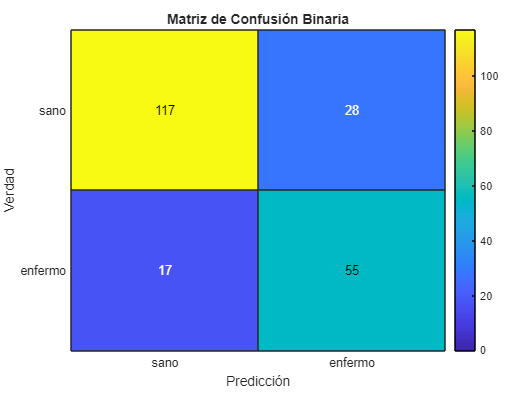

% % EVALUAR EL MODELO BINARIO
% % Preparar datos de test
% %y_test = categorical(data_test.Clase);
% y_test = repmat("enfermo", height(data_test), 1);
% y_test(strcmp(data_test.Clase, 'sano')) = "sano";
% y_test = categorical(y_test);
% 
% features_test = data_test(:, {'Leu_median_Intensity','GlobulosBlancosDetectados','Leu_median_Circularity','Par_median_Intensity'});
% x_test = table2array(features_test);
% 
% % Cargar modelo complejo
% modelo_PBL = load('model_LogisticRegression.mat');
% modelo_PBL = modelo_PBL.model_LogisticRegression;
% [predictions, scores] = predict(modelo_PBL, x_test); % Predecir si es falciparum, vivax o sano
% y_prediction = categorical(predictions);
% 
% % Evaluar el rendimienot del modelo
% conf_mat = confusionmat(y_test, y_prediction);
% figure;
% h = heatmap(["sano","enfermo"], ["sano","enfermo"], conf_mat, ...
%     'Colormap', parula, 'ColorLimits', [0 max(conf_mat(:))]);
% h.XLabel = 'Predicción';
% h.YLabel = 'Verdad';
% title('Matriz de Confusión Binaria');
% 

% % Accuracy, sensibilidad y especificidad del modelo
% clases = categories(y_test);
% accuracy = zeros(length(clases),1);
% sensibilidad = zeros(length(clases),1);
% especificidad = zeros(length(clases),1);
% for i = 1:length(clases)
%     clase_i = clases{i};
% 
%     % Verdaderos positivos 
%     TP = sum((y_test == clase_i) & (y_prediction == clase_i));
% 
%     % Falsos negativos 
%     FN = sum((y_test == clase_i) & (y_prediction ~= clase_i));
% 
%     % Verdaderos negativos 
%     TN = sum((y_test ~= clase_i) & (y_prediction ~= clase_i));
% 
%     % Falsos positivos 
%     FP = sum((y_test ~= clase_i) & (y_prediction == clase_i));
% 
%     accuracy(i) = (TP + TN) / (TP + TN + FP + FN);
%     sensibilidad(i) = TP / (TP + FN);
%     especificidad(i) = TN / (TN + FP);
% 
%     fprintf('Clase: %s\n', clase_i);
%     fprintf('Accuracy: %.2f%%\n', accuracy(i)*100);
%     fprintf('Sensibilidad: %.2f%%\n', sensibilidad(i)*100);
%     fprintf('Especificidad: %.2f%%\n', especificidad(i)*100);
% end


Clase: enfermo


Accuracy: 79.26%


Sensibilidad: 80.69%


Especificidad: 76.39%


Clase: sano


Accuracy: 79.26%


Sensibilidad: 76.39%


Especificidad: 80.69%



% % Predecir una nueva imagen (validación)
% nueva_imagen_data = readtable('Prueba_S.csv');
% x_nueva = table2array(nueva_imagen_data(:, {'Leu_median_Intensity','GlobulosBlancosDetectados','Leu_median_Circularity','Par_median_Intensity'}));
% 
% [predictions, scores] = predict(modelo_PBL, x_nueva);
% 
% for i = 1:height(nueva_imagen_data)
%      clase_predicha = string(predictions(i));
%      probabilidades = scores(i,:);
% 
%      fprintf('\n--- Imagen %d ---\n', i);
%      fprintf('Predicción: %s\n', string(clase_predicha));
%      disp('Probabilidades por clase:');
%      disp(table(modelo_PBL.ClassNames, probabilidades', 'VariableNames', {'Clase', 'Probabilidad'}));
% end

#### Random Forest (100)

% rng(55);


--- Imagen 1 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.086957  
    sano          0.91304  




--- Imagen 2 ---


Predicción: enfermo


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo        0.6     
    sano           0.4     




--- Imagen 3 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.086957  
    sano          0.91304  




--- Imagen 4 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.086957  
    sano          0.91304  




--- Imagen 5 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.035714  
    sano          0.96429  




--- Imagen 6 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.086957  
    sano          0.91304  




--- Imagen 7 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.035714  
    sano          0.96429  




--- Imagen 8 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.086957  
    sano          0.91304  




--- Imagen 9 ---


Predicción: enfermo


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo        0.6     
    sano           0.4     




--- Imagen 10 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.086957  
    sano          0.91304  




--- Imagen 11 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.035714  
    sano          0.96429  




--- Imagen 12 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.035714  
    sano          0.96429  




--- Imagen 13 ---


Predicción: enfermo


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo        0.6     
    sano           0.4     




--- Imagen 14 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo         0      
    sano            1      




--- Imagen 15 ---


Predicción: enfermo


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo        0.6     
    sano           0.4     




--- Imagen 16 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.086957  
    sano          0.91304  




--- Imagen 17 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.086957  
    sano          0.91304  




--- Imagen 18 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.086957  
    sano          0.91304  




--- Imagen 19 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.035714  
    sano          0.96429  




--- Imagen 20 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.086957  
    sano          0.91304  




--- Imagen 21 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.035714  
    sano          0.96429  




--- Imagen 22 ---


Predicción: sano


Probabilidades por clase:


     Clase     Probabilidad
    _______    ____________

    enfermo      0.28571   
    sano         0.71429   



% 
% y_train = categorical(data_train.Clase);
% features_training = data_train(:, {'GlobulosBlancosDetectados','ParasitosDetectados','Leu_median_Circularity', 'Par_median_Circularity', ...
%                     'Leu_median_Intensity', 'Par_median_Intensity'});
% x_train = table2array(features_training);
% 
% model_RandomForest100 = TreeBagger(100, X_train, Y_train, 'OOBPrediction','on','Method','classification','MinLeafSize',10,'OOBPredictorImportance','on','CVPartition',cv_in);
% 
% save('model_RandomForest100.mat', 'model_RandomForest100', 'features_training');

% ============================================================================%
% rng(55);
% 
% Y_train = categorical(data_train.Clase);
% features_training = data_train(:, {'Par_median_Circularity', ...
%                      'Leu_median_Intensity','GlobulosBlancosDetectados','ParasitosDetectados','Leu_median_Circularity','Par_median_Intensity'});
% X_train = table2array(features_training);
% 
% template = templateTree('MinLeafSize', 10);
% model_RandomForest100 = fitcensemble(X_train, Y_train, ...
%     'Method', 'Bag', ...
%     'Learners', template, ...
%     'NumLearningCycles', 100, ...
%     'CVPartition', cv_in);
% save('model_RandomForest100.mat', 'model_RandomForest100');

% EVALUAR EL MODELO
% modelo_PBL = load('model_RandomForest100.mat');
% modelo_PBL = modelo_PBL.model_RandomForest100;
% 
% loss_modelo = kfoldLoss(modelo_PBL)
% Y_pred = kfoldPredict(modelo_PBL);
% Y_train = categorical(Y_train);  
% Y_pred = categorical(Y_pred);
% 
% % Confusion matrix
% conf_mat = confusionmat(Y_train, Y_pred);
% figure;
% h = heatmap(conf_mat, 'Colormap', parula, 'ColorLimits', [0 max(conf_mat(:))]);
% h.XLabel = 'Predicción';
% h.YLabel = 'Verdad';
% title('Matriz de Confusión RF 100');
% 
% % Accuracy, Sensibilidad y Especifidad
% clases = categories(Y_train);
% accuracy = zeros(length(clases),1);
% sensibilidad = zeros(length(clases),1);
% especificidad = zeros(length(clases),1);
% for i = 1:length(clases)
%     clase_i = clases{i};
%     
%     % Verdaderos positivos 
%     TP = sum((Y_train == clase_i) & (Y_pred == clase_i));
%     
%     % Falsos negativos 
%     FN = sum((Y_train == clase_i) & (Y_pred ~= clase_i));
%     
%     % Verdaderos negativos 
%     TN = sum((Y_train ~= clase_i) & (Y_pred ~= clase_i));
%     
%     % Falsos positivos 
%     FP = sum((Y_train ~= clase_i) & (Y_pred == clase_i));
%     
%     accuracy(i) = (TP + TN) / (TP + TN + FP + FN);
%     sensibilidad(i) = TP / (TP + FN);
%     especificidad(i) = TN / (TN + FP);
%     
%     fprintf('Clase: %s\n', clase_i);
%     fprintf('Accuracy: %.2f%%\n', accuracy(i)*100);
%     fprintf('Sensibilidad: %.2f%%\n', sensibilidad(i)*100);
%     fprintf('Especificidad: %.2f%%\n', especificidad(i)*100);
% end

% VALIDACIÓN CON NUEVA IMAGEN
% nueva_imagen_data = readtable('Prueba_V.csv');
% 
% x_nueva = table2array(nueva_imagen_data(:, {'Par_median_Circularity', ...
%                      'Leu_median_Intensity','GlobulosBlancosDetectados','ParasitosDetectados','Leu_median_Circularity','Par_median_Intensity'}));
% 
% [predictions, scores] = predict(modelo_PBL.Trained{1}, x_nueva); % Predecir si es falciparum, vivax o sano
% 
% for i = 1:height(nueva_imagen_data)
%     clase_predicha = string(predictions(i));
%     probabilidades = scores(i,:);  
% 
%     % Densidad parasitaria (parásitos/μL)
%     parasitos = nueva_imagen_data.ParasitosDetectados(i);
%     leucocitos = nueva_imagen_data.GlobulosBlancosDetectados(i);
% 
%     if (leucocitos + parasitos == 0)
%         densidad_parasitaria = 0;
%     else
%         factor = 400; % es el mas comun --> convierte la proporcion de parasitos en una densidad parasitaria
%         densidad_parasitaria = (parasitos / (leucocitos + parasitos)*factor);
%     end
% 
%     % Clasificar segun los umbrales
%     if strcmp(clase_predicha, 'sano')
%         categoria_densidad = 'Sano';
%     else
%         if strcmp(clase_predicha, 'falciparum')
%             if densidad_parasitaria < 800
%                 categoria_densidad = 'Baja';
%             elseif densidad_parasitaria <= 4000
%                 categoria_densidad = 'Moderada';
%             else
%                 categoria_densidad = 'Alta';
%             end
%         end
%         if strcmp(clase_predicha, 'vivax')
%             if densidad_parasitaria < 800
%                 categoria_densidad = 'Baja';
%             elseif densidad_parasitaria <= 2400
%                 categoria_densidad = 'Moderada';
%             else
%                 categoria_densidad = 'Alta';
%             end
%         end
%     end
% 
%     fprintf('\n--- Imagen %d ---\n', i);
%     fprintf('Predicción: %s\n', string(clase_predicha));
%     disp('Probabilidades por clase:');
%     disp(table(modelo_PBL.ClassNames, probabilidades', 'VariableNames', {'Clase', 'Probabilidad'}));
%     fprintf('Densidad parasitaria estimada: %.2f parásitos/μL\n', densidad_parasitaria);
%     fprintf('Densidad parasitaria: %s\n', categoria_densidad);
% end

#### Random Forest (200)

% % COMPROBAR SI HAY QUE QUTAR LAS 2 PRIMERAS VARIABLES
% rng(55);
% 
% y_train = categorical(data_train.Clase);
% features_training = data_train(:, {'GlobulosBlancosDetectados','ParasitosDetectados','Leu_median_Circularity', 'Par_median_Circularity', ...
%                     'Leu_median_Intensity', 'Par_median_Intensity'});
% x_train = table2array(features_training);
% 
% model_RandomForest200 = TreeBagger(200, x_train, y_train, 'OOBPrediction','on','Method','classification');
% 
% save('model_RandomForest200.mat', 'model_RandomForest200', 'features_training');

#### Support Vector Machines (SVM)

% rng(55);
% 
% y_train = categorical(data_train.Clase);
% features_training = data_train(:, {'GlobulosBlancosDetectados','ParasitosDetectados','Leu_median_Circularity', 'Par_median_Circularity', ...
%                     'Leu_median_Intensity', 'Par_median_Intensity'});
% x_train = table2array(features_training);
% 
% template = templateSVM("BoxConstraint",0.5,'KernelFunction','rbf','Standardize',true,'KernelScale','auto');
% model_SVM = fitcecoc(x_train,y_train,'Learners',template,'Coding','onevsone','Verbose',2);
% 
% save('model_SVM.mat', 'model_SVM', 'features_training');

#### k-Nearest Neighbors (k-NN)

% rng(55);
% 
% y_train = categorical(data_train.Clase);
% features_training = data_train(:, {'GlobulosBlancosDetectados','ParasitosDetectados','Leu_median_Circularity', 'Par_median_Circularity', ...
%                     'Leu_median_Intensity', 'Par_median_Intensity'});
% x_train = table2array(features_training);
% 
% model_kNN = fitcknn(x_train,y_train,'NumNeighbors',7,'Distance','cosine','DistanceWeight','inverse','Standardize',true);
% 
% save('model_kNN.mat', 'model_kNN', 'features_training');

#### Comprobaciones

- **Accuracy**: el porcentaje total de predicciones correctas.

- **Sensibilidad**: la capacidad del modelo para detectar los positivos reales --> mide: falsos negativos.

- **Especifidad**: la capacidad del modelo para detectar los negativos reales --> mide: falsos positivos.

% % Preparar datos de test
% y_test = categorical(data_test.Clase);
% features_test = data_test(:, {'Par_median_Circularity', ...
%                      'Leu_median_Intensity','GlobulosBlancosDetectados','ParasitosDetectados','Leu_median_Circularity','Par_median_Intensity'});
% x_test = table2array(features_test);
% 
% % Cargar modelo complejo
% modelo_PBL = load('model_LogisticRegression.mat');
% modelo_PBL = modelo_PBL.model_LogisticRegression;
% [predictions, scores] = predict(modelo_PBL, x_test); % Predecir si es falciparum, vivax o sano
% y_prediction = categorical(predictions);
% 
% % Evaluar el rendimienot del modelo
% conf_mat = confusionmat(y_test, y_prediction);
% figure;
% h = heatmap(conf_mat, 'Colormap', parula, 'ColorLimits', [0 max(conf_mat(:))]);
% h.XLabel = 'Predicción';
% h.YLabel = 'Verdad';
% title('Matriz de Confusión RF 100');
% 
% % Accuracy, sensibilidad y especificidad del modelo
% clases = categories(y_test);
% accuracy = zeros(length(clases),1);
% sensibilidad = zeros(length(clases),1);
% especificidad = zeros(length(clases),1);
% for i = 1:length(clases)
%     clase_i = clases{i};
%     
%     % Verdaderos positivos 
%     TP = sum((y_test == clase_i) & (y_prediction == clase_i));
%     
%     % Falsos negativos 
%     FN = sum((y_test == clase_i) & (y_prediction ~= clase_i));
%     
%     % Verdaderos negativos 
%     TN = sum((y_test ~= clase_i) & (y_prediction ~= clase_i));
%     
%     % Falsos positivos 
%     FP = sum((y_test ~= clase_i) & (y_prediction == clase_i));
%     
%     accuracy(i) = (TP + TN) / (TP + TN + FP + FN);
%     sensibilidad(i) = TP / (TP + FN);
%     especificidad(i) = TN / (TN + FP);
%     
%     fprintf('Clase: %s\n', clase_i);
%     fprintf('Accuracy: %.2f%%\n', accuracy(i)*100);
%     fprintf('Sensibilidad: %.2f%%\n', sensibilidad(i)*100);
%     fprintf('Especificidad: %.2f%%\n', especificidad(i)*100);
% end
% 
% 
% % Predecir una nueva imagen (validación)
% nueva_imagen_data = readtable('Prueba_V.csv');
% x_nueva = table2array(nueva_imagen_data(:, {'Par_median_Circularity', ...
%                      'Leu_median_Intensity','GlobulosBlancosDetectados','ParasitosDetectados','Leu_median_Circularity','Par_median_Intensity'}));
% 
% [predictions, scores] = predict(modelo_PBL, x_nueva); % Predecir si es falciparum, vivax o sano
% for i = 1:height(nueva_imagen_data)
%     clase_predicha = string(predictions(i));
%     probabilidades = scores(i,:);  
% 
%     % Densidad parasitaria (parásitos/μL)
%     parasitos = nueva_imagen_data.ParasitosDetectados(i);
%     leucocitos = nueva_imagen_data.GlobulosBlancosDetectados(i);
% 
%     if (leucocitos + parasitos == 0)
%         densidad_parasitaria = 0;
%     else
%         factor = 400; % es el mas comun --> convierte la proporcion de parasitos en una densidad parasitaria
%         densidad_parasitaria = (parasitos / (leucocitos + parasitos)*factor);
%     end
% 
%     % Clasificar segun los umbrales
%     if strcmp(clase_predicha, 'sano')
%         categoria_densidad = 'Sano';
%     else
%         if strcmp(clase_predicha, 'falciparum')
%             if densidad_parasitaria < 800
%                 categoria_densidad = 'Baja';
%             elseif densidad_parasitaria <= 4000
%                 categoria_densidad = 'Moderada';
%             else
%                 categoria_densidad = 'Alta';
%             end
%         end
%         if strcmp(clase_predicha, 'vivax')
%             if densidad_parasitaria < 800
%                 categoria_densidad = 'Baja';
%             elseif densidad_parasitaria <= 2400
%                 categoria_densidad = 'Moderada';
%             else
%                 categoria_densidad = 'Alta';
%             end
%         end
%     end
% 
%     fprintf('\n--- Imagen %d ---\n', i);
%     fprintf('Predicción: %s\n', string(clase_predicha));
%     disp('Probabilidades por clase:');
%     disp(table(modelo_PBL.ClassNames, probabilidades', 'VariableNames', {'Clase', 'Probabilidad'}));
%     fprintf('Densidad parasitaria estimada: %.2f parásitos/μL\n', densidad_parasitaria);
%     fprintf('Densidad parasitaria: %s\n', categoria_densidad);
% end